# Codigos de Proyecto 

- Sección: 3

- N° de grupo: 2

- Titulo del Proyecto: Simulación numérica de la recuperación exponencial de una carga eléctrica a través del modelo ERL

- Integrante 1 (líder): Burgos Ochoa, Joseph Imanol – 202510395 – Participación: 100 %

- Integrante 2: Silvera Pastor, José María – 202510530 – Participación: 100 %

- Integrante 3: Neciosup Abanto, Edwin Jeremy – 202510425 – Participación: 100 %

- Integrante 4: Reyna De La Gala, Carlo Francesco – 202510333 – Participación: 100 %

- Integrante 5: Corrales Rincón, Juan Pablo – 202510282 – Participación: 100 %

**Observación:** 

- No olvidar añadir el porcentaje de participación.

- Incluir comentarios relevantes para entender el codigo, tener en cuenta que comentarios de IA anularan la entrega

- El codgio debe de tener una identacion adecuada para facilitar su lectura

- El codigo debe der replicable en cualquier computadora (Uso adecuado de semillas para funciones)

- Las funciones principales deben de ir en la parte inferior de este archivo

- Titulos de los codigos deben reflejar su funcionalidad

## Configuración inicial y formato de figuras

clear; clc; close all;
rng(0);   % semilla fija

% Formato de las figuras 
set(0,'DefaultAxesFontSize',12,'DefaultTextFontSize',12,'DefaultLineLineWidth',1.5);
try
    set(0,'DefaultLegendFontSize',11);
catch
end
outdir = 'figuras';
if ~exist(outdir,'dir')
    mkdir(outdir);
end

## Parámetros del modelo y de la perturbación

% Valores estimados a partir Rodríguez et al. (2015), (load 30)
V0  = 1.0;                                            % tensión nominal [p.u.]
act = struct('S0',0.111,'Ns',0.98292799,'Nt',2.37985285,'T',0.00688679);  % potencia activa  (P0,Nps,Npt,Tp)
rea = struct('S0',0.052,'Ns',1.28242865,'Nt',2.19255439,'T',0.00788255);  % potencia reactiva(Q0,Nqs,Nqt,Tq)

% Hueco de tensión 
sag  = struct('t0',1.0,'delta',0.20,'dur',0.5);       % t0 [s], profundidad, duración [s]
Tend = 5.0;                                           % horizonte de simulación [s]

Tmin = min(act.T, rea.T);                          
met  = {'Euler','RK4','AB4'};
col  = [0.000 0.447 0.741;  0.466 0.674 0.188;  0.850 0.325 0.098];

## Análisis de estabilidad teórica

hv = linspace(0,4,8001);
R  = zeros(3,numel(hv));
R(1,:) = abs(1 - hv);
R(2,:) = abs(1 - hv + hv.^2/2 - hv.^3/6 + hv.^4/24);
for i = 1:numel(hv)
    z = -hv(i);
    % polinomio característico de AB4:  r^4-(1+55z/24)r^3+(59z/24)r^2-(37z/24)r+9z/24 = 0
    R(3,i) = max(abs(roots([1, -(1+55*z/24), 59*z/24, -37*z/24, 9*z/24])));
end
hcrit = zeros(1,3);                                   % límite de estabilidad en h = dt/T
for m = 1:3
    idx = find(hv>0 & R(m,:) > 1+1e-9, 1, 'first');
    hcrit(m) = hv(idx-1);
end
dtcritP = hcrit*act.T;                                % paso máximo estable, canal P
dtcritQ = hcrit*rea.T;                                % paso máximo estable, canal Q
dtcrit  = hcrit*Tmin;                                 % paso máximo estable del sistema (P y Q)
fprintf('\n=== ESTABILIDAD TEÓRICA (Tp = %.4f s, Tq = %.4f s) ===\n',act.T,rea.T);


=== ESTABILIDAD TEÓRICA (Tp = 0.0069 s, Tq = 0.0079 s) ===


fprintf('%-6s %-8s %-12s %-12s %-12s\n','Método','h_crit','dt_max P [s]','dt_max Q [s]','dt_max sist.');

Método h_crit   dt_max P [s] dt_max Q [s] dt_max sist.


for m = 1:3
    fprintf('%-6s %-8.3f %-12.5f %-12.5f %-12.5f\n',met{m},hcrit(m),dtcritP(m),dtcritQ(m),dtcrit(m));
end

Euler  2.000    0.01377      0.01577      0.01377     
RK4    2.785    0.01918      0.02195      0.01918     
AB4    0.300    0.00207      0.00236      0.00207     


## Caso base (dt = 1e-3 s)

h0 = 1e-3;
resP = cell(1,3); resQ = cell(1,3);
for m = 1:3
    resP{m} = caso(act, h0, met{m}, sag, Tend, V0);
    resQ{m} = caso(rea, h0, met{m}, sag, Tend, V0);
end
t = resP{1}.t;

fprintf('\n=== CASO BASE (dt = %g s): error relativo máximo y costo ===\n',h0);


=== CASO BASE (dt = 0.001 s): error relativo máximo y costo ===


fprintf('%-6s %-12s %-12s %-14s %-14s %-10s\n','Método','Error P_d','Error Q_d','Eval. f (P)','Eval. f (P+Q)','Estable');

Método Error P_d    Error Q_d    Eval. f (P)    Eval. f (P+Q)  Estable   


for m = 1:3
    ok = (h0/act.T < hcrit(m)) && (h0/rea.T < hcrit(m));
    fprintf('%-6s %-12.2e %-12.2e %-14d %-14d %-10s\n',met{m},resP{m}.err,resQ{m}.err,resP{m}.nf,resP{m}.nf+resQ{m}.nf,mat2str(ok));
end

Euler  8.55e-03     4.89e-03     5000           10000          true      
RK4    4.60e-07     1.74e-07     20000          40000          true      
AB4    1.34e-05     5.40e-06     5027           10054          true      


## **Representación de la respuesta de la potencia activa y reactiva frente a la perturbación de tensión**

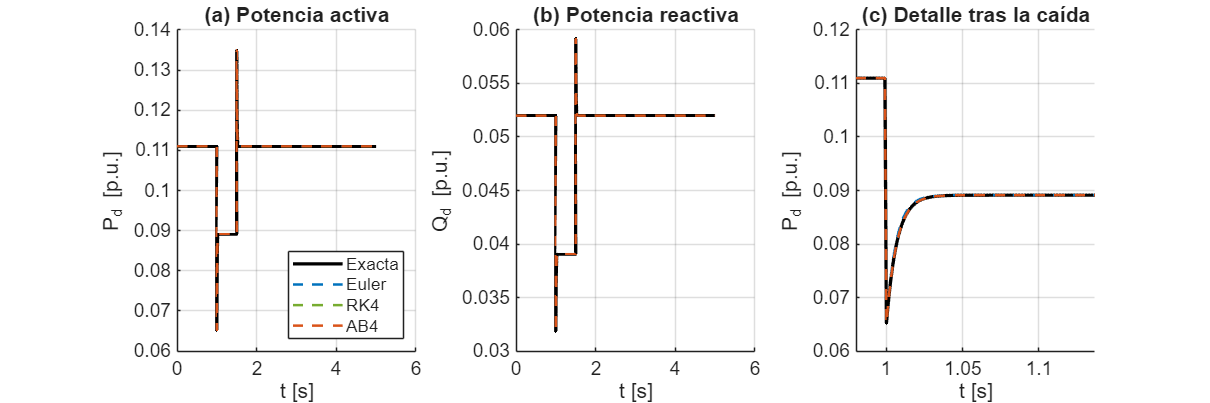

figure('Position',[100 100 1200 400],'Color','w');

subplot(1,3,1); hold on; grid on;
plot(t, resP{1}.Pex, 'k', 'LineWidth', 2);
for m = 1:3
    plot(t, resP{m}.P, '--', 'Color', col(m,:));
end
xlabel('t [s]'); ylabel('P_d [p.u.]'); title('(a) Potencia activa');
legend('Exacta', met{:}, 'Location', 'southeast');

subplot(1,3,2); hold on; grid on;
plot(t, resQ{1}.Pex, 'k', 'LineWidth', 2);
for m = 1:3
    plot(t, resQ{m}.P, '--', 'Color', col(m,:));
end
xlabel('t [s]'); ylabel('Q_d [p.u.]'); title('(b) Potencia reactiva');


% Zoom de la recuperación exponencial después de la caída
w = t >= sag.t0 - 0.02 & t <= sag.t0 + 20*act.T;
subplot(1,3,3); hold on; grid on;
plot(t(w), resP{1}.Pex(w), 'k', 'LineWidth', 2);
for m = 1:3
    plot(t(w), resP{m}.P(w), '--', 'Color', col(m,:));
end
xlabel('t [s]'); ylabel('P_d [p.u.]'); title('(c) Detalle tras la caída');

print(gcf, 'figuras/fig1_respuestas.png', '-dpng', '-r300');

## Convergencia frente al paso (dt)

hlist = [1e-4 2e-4 2.5e-4 5e-4 1e-3 2e-3 2.5e-3 5e-3 1e-2 2e-2 2.5e-2 5e-2 1e-1]; % todos dividen 0.5 y 1.0
nh = numel(hlist);
errP = nan(3,nh); errQ = nan(3,nh); nfun = nan(3,nh);
estP = false(3,nh); estQ = false(3,nh);
errSR = nan(1,nh);                                   % AB4 sin reinicio (para realizar comparación)
for j = 1:nh
    for m = 1:3
        rp = caso(act, hlist(j), met{m}, sag, Tend, V0);
        rq = caso(rea, hlist(j), met{m}, sag, Tend, V0);
        errP(m,j) = rp.err; errQ(m,j) = rq.err; nfun(m,j) = rp.nf;  
        estP(m,j) = hlist(j)/act.T < hcrit(m);
        estQ(m,j) = hlist(j)/rea.T < hcrit(m);
    end
    errSR(j) = caso(act, hlist(j), 'AB4sr', sag, Tend, V0).err;
end
err = errP; estable = estP;                         
errSys = max(errP,errQ); estSys = estP & estQ;       

% Orden observado (regresión log-log en la zona estable y asintótica dt <= 2e-3)
fprintf('\n=== ORDEN DE CONVERGENCIA OBSERVADO (P_d | Q_d) ===\n');


=== ORDEN DE CONVERGENCIA OBSERVADO (P_d | Q_d) ===


for m = 1:3
    sel = estP(m,:) & hlist <= 2e-3;
    pP = polyfit(log(hlist(sel)),log(errP(m,sel)),1);
    sel = estQ(m,:) & hlist <= 2e-3;
    pQ = polyfit(log(hlist(sel)),log(errQ(m,sel)),1);
    fprintf('%-6s p_obs(P) = %.2f | p_obs(Q) = %.2f\n',met{m},pP(1),pQ(1));
end

Euler  p_obs(P) = 1.04 | p_obs(Q) = 1.04
RK4    p_obs(P) = 4.07 | p_obs(Q) = 4.06
AB4    p_obs(P) = 3.89 | p_obs(Q) = 3.90


## **Representación gráfica de las zonas de convergencia y divergencia**

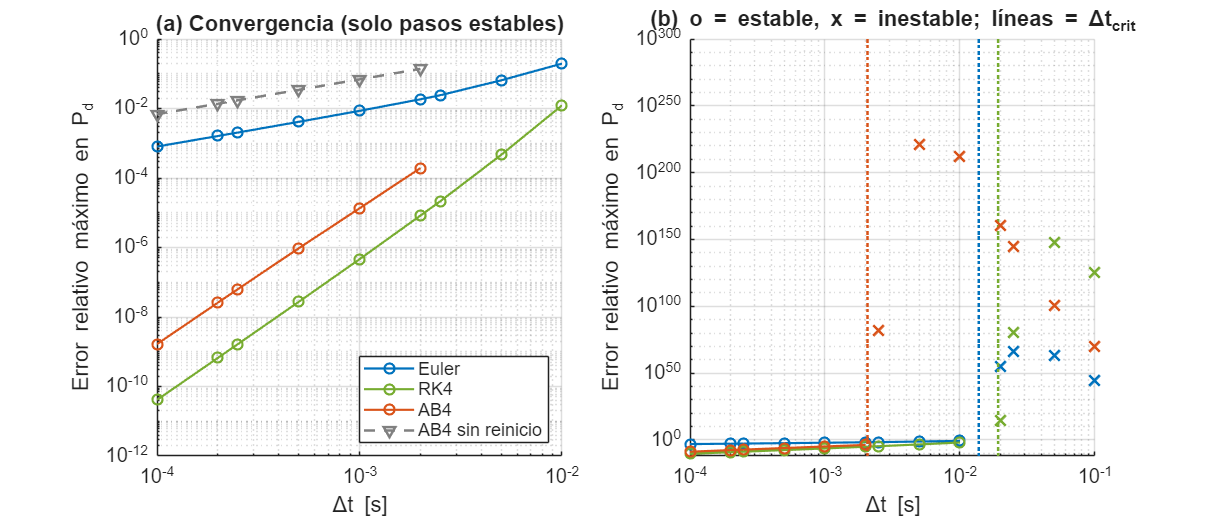


fig2 = figure('Position',[100 100 1000 430],'Color','w');
subplot(1,2,1); hold on; grid on;
for m = 1:3
    s = estable(m,:);
    loglog(hlist(s),err(m,s),'-o','Color',col(m,:),'LineWidth',1.3);
end
loglog(hlist(estable(3,:)),errSR(estable(3,:)),'--v','Color',[.5 .5 .5]);
set(gca,'XScale','log','YScale','log');
xlabel('\Deltat [s]'); ylabel('Error relativo máximo en P_d');
title('(a) Convergencia (solo pasos estables)');
legend([met,{'AB4 sin reinicio'}],'Location','southeast');

subplot(1,2,2); hold on; grid on;
for m = 1:3
    s = estable(m,:);
    e = err(m,:); e(~isfinite(e)) = 1e300;
    loglog(hlist(s),e(s),'-o','Color',col(m,:),'LineWidth',1.3);
    loglog(hlist(~s),e(~s),'x','Color',col(m,:),'MarkerSize',9,'LineWidth',1.5);
    plot(dtcritP(m)*[1 1],[1e-12 1e300],':','Color',col(m,:));
end
set(gca,'XScale','log','YScale','log'); ylim([1e-12 1e300]);
xlabel('\Deltat [s]'); ylabel('Error relativo máximo en P_d');
title('(b) o = estable, x = inestable; líneas = \Deltat_{crit}');
print(fig2,fullfile(outdir,'fig2_convergencia.png'),'-dpng','-r300');

## Límite de estabilidad empírico vs teórico

rr  = linspace(0.05,3.5,150);
nn  = unique(max(round(0.5./(rr*act.T)),1));
dts = sort(0.5./nn);                                 
dt_emp = zeros(1,3);
for m = 1:3
    dt_emp(m) = dts(end);
    for j = 1:numel(dts)
        r = caso(act,dts(j),met{m},sag,Tend,V0);
        if diverge(r,Tend)
            dt_emp(m) = dts(max(j-1,1)); break
        end
    end
end
fprintf('\n=== LÍMITE DE ESTABILIDAD (canal P, Tp = %.4f s) ===\n',act.T);


=== LÍMITE DE ESTABILIDAD (canal P, Tp = 0.0069 s) ===


fprintf('%-6s %-14s %-14s %-10s\n','Método','dt_max teórico','dt_max empír.','Dif. [%]');

Método dt_max teórico dt_max empír.  Dif. [%]  


for m = 1:3
    fprintf('%-6s %-14.5f %-14.5f %-10.1f\n',met{m},dtcritP(m),dt_emp(m),100*(dt_emp(m)-dtcritP(m))/dtcritP(m));
end

Euler  0.01377        0.01351        -1.9      
RK4    0.01918        0.01852        -3.4      
AB4    0.00207        0.00194        -6.2      


## Costo computacional vs precisión

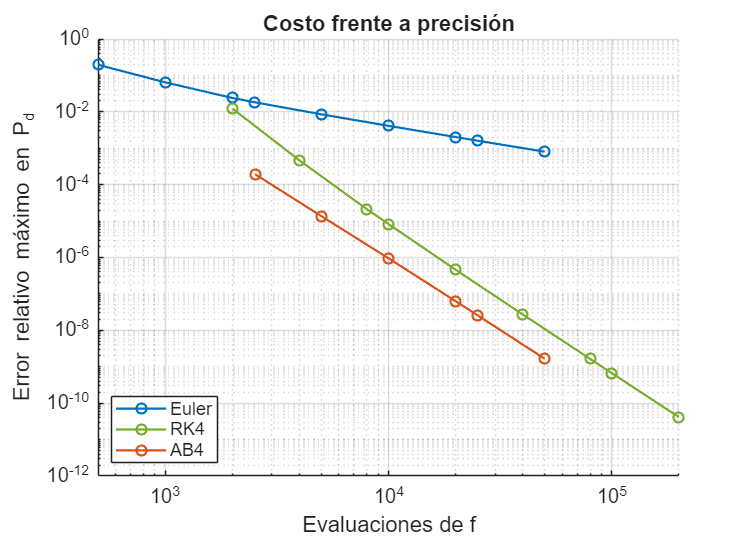

fig4 = figure('Position',[100 100 600 430],'Color','w'); hold on; grid on;
for m = 1:3
    s = estable(m,:);
    loglog(nfun(m,s),err(m,s),'-o','Color',col(m,:),'LineWidth',1.3);
end
set(gca,'XScale','log','YScale','log');
xlabel('Evaluaciones de f'); ylabel('Error relativo máximo en P_d');
title('Costo frente a precisión'); legend(met,'Location','southwest');
print(fig4,fullfile(outdir,'fig4_costo.png'),'-dpng','-r300');

## Robustez: variación de la profundidad del hueco de tensión y de los parámetros

% Profundidad del hueco de tensión(dt fijo = 1e-3 s)
deltas = [0.05 0.10 0.20 0.30 0.40];
fprintf('\n=== PROFUNDIDAD DEL HUECO DE TENSIÓN (dt = 1e-3 s): error relativo máximo ===\n');


=== PROFUNDIDAD DEL HUECO DE TENSIÓN (dt = 1e-3 s): error relativo máximo ===


fprintf('%-6s | %-10s %-10s %-10s | %-10s %-10s %-10s\n','delta','P:Euler','P:RK4','P:AB4','Q:Euler','Q:RK4','Q:AB4');

delta  | P:Euler    P:RK4      P:AB4      | Q:Euler    Q:RK4      Q:AB4     


for d = deltas
    sg = sag; sg.delta = d; eP = zeros(1,3); eQ = zeros(1,3);
    for m = 1:3
        eP(m) = caso(act,1e-3,met{m},sg,Tend,V0).err;
        eQ(m) = caso(rea,1e-3,met{m},sg,Tend,V0).err;
    end
    fprintf('%-6.2f | %-10.2e %-10.2e %-10.2e | %-10.2e %-10.2e %-10.2e\n',d,eP,eQ);
end

0.05   | 2.02e-03   1.09e-07   3.30e-06   | 1.14e-03   4.09e-08   1.29e-06  
0.10   | 4.11e-03   2.22e-07   6.64e-06   | 2.34e-03   8.35e-08   2.61e-06  
0.20   | 8.55e-03   4.60e-07   1.34e-05   | 4.89e-03   1.74e-07   5.40e-06  
0.30   | 1.33e-02   7.16e-07   2.04e-05   | 7.69e-03   2.74e-07   8.37e-06  
0.40   | 1.86e-02   9.95e-07   2.75e-05   | 1.08e-02   3.85e-07   1.16e-05  


% Se evalúa la variacion de cada parámetro por separado, alrededor del
% valor obtenido en la literatura (valor base)
% Se evalúan valores menores y mayores que el base, con el mismo paso dt = 1 ms.
fT = [0.50 0.75 1.00 1.25 1.50];                    
dN = [-0.6 -0.3 0 0.3 0.6];                          
args = {act,rea,met,sag,Tend,V0,hcrit};
barrido_param('Tp','Tp','P','T',act.T*fT,args{:},h0);


=== Tp (dt = 0.001 s): error relativo máximo ===
Tp       | P_d: Euler  RK4  AB4              | Q_d: Euler  RK4  AB4             
0.0034434 |  1.84e-02  8.31e-06  1.93e-04     |  4.89e-03  1.74e-07  5.40e-06    
0.00516509 |  1.16e-02  1.51e-06  4.03e-05     |  4.89e-03  1.74e-07  5.40e-06    
0.00688679 |  8.55e-03  4.60e-07  1.34e-05     |  4.89e-03  1.74e-07  5.40e-06      <- base
0.00860849 |  6.73e-03  1.84e-07  5.76e-06     |  4.89e-03  1.74e-07  5.40e-06    
0.0103302 |  5.57e-03  8.72e-08  2.86e-06     |  4.89e-03  1.74e-07  5.40e-06    


barrido_param('Tq','Tq','Q','T',rea.T*fT,args{:},h0);


=== Tq (dt = 0.001 s): error relativo máximo ===
Tq       | P_d: Euler  RK4  AB4              | Q_d: Euler  RK4  AB4             
0.00394128 |  8.55e-03  4.60e-07  1.34e-05     |  1.04e-02  3.09e-06  7.59e-05    
0.00591191 |  8.55e-03  4.60e-07  1.34e-05     |  6.65e-03  5.69e-07  1.61e-05    
0.00788255 |  8.55e-03  4.60e-07  1.34e-05     |  4.89e-03  1.74e-07  5.40e-06      <- base
0.00985319 |  8.55e-03  4.60e-07  1.34e-05     |  3.86e-03  7.00e-08  2.30e-06    
0.0118238 |  8.55e-03  4.60e-07  1.34e-05     |  3.19e-03  3.33e-08  1.14e-06    


barrido_param('Nps','Nps','P','Ns',max(act.Ns+dN,0),args{:},h0);


=== Nps (dt = 0.001 s): error relativo máximo ===
Nps      | P_d: Euler  RK4  AB4              | Q_d: Euler  RK4  AB4             
0.382928 |  1.20e-02  6.45e-07  1.85e-05     |  4.89e-03  1.74e-07  5.40e-06    
0.682928 |  1.03e-02  5.54e-07  1.60e-05     |  4.89e-03  1.74e-07  5.40e-06    
0.982928 |  8.55e-03  4.60e-07  1.34e-05     |  4.89e-03  1.74e-07  5.40e-06      <- base
1.28293  |  6.77e-03  3.64e-07  1.07e-05     |  4.89e-03  1.74e-07  5.40e-06    
1.58293  |  4.95e-03  2.67e-07  7.95e-06     |  4.89e-03  1.74e-07  5.40e-06    


barrido_param('Npt','Npt','P','Nt',max(act.Nt+dN,0),args{:},h0);


=== Npt (dt = 0.001 s): error relativo máximo ===
Npt      | P_d: Euler  RK4  AB4              | Q_d: Euler  RK4  AB4             
1.77985  |  4.95e-03  2.67e-07  7.95e-06     |  4.89e-03  1.74e-07  5.40e-06    
2.07985  |  6.77e-03  3.64e-07  1.07e-05     |  4.89e-03  1.74e-07  5.40e-06    
2.37985  |  8.55e-03  4.60e-07  1.34e-05     |  4.89e-03  1.74e-07  5.40e-06      <- base
2.67985  |  1.03e-02  5.54e-07  1.60e-05     |  4.89e-03  1.74e-07  5.40e-06    
2.97985  |  1.20e-02  6.45e-07  1.85e-05     |  4.89e-03  1.74e-07  5.40e-06    


barrido_param('Nqs','Nqs','Q','Ns',max(rea.Ns+dN,0),args{:},h0);


=== Nqs (dt = 0.001 s): error relativo máximo ===
Nqs      | P_d: Euler  RK4  AB4              | Q_d: Euler  RK4  AB4             
0.682429 |  8.55e-03  4.60e-07  1.34e-05     |  7.97e-03  2.84e-07  8.67e-06    
0.982429 |  8.55e-03  4.60e-07  1.34e-05     |  6.44e-03  2.30e-07  7.06e-06    
1.28243  |  8.55e-03  4.60e-07  1.34e-05     |  4.89e-03  1.74e-07  5.40e-06      <- base
1.58243  |  8.55e-03  4.60e-07  1.34e-05     |  3.30e-03  1.18e-07  3.68e-06    
1.88243  |  8.55e-03  4.60e-07  1.34e-05     |  1.69e-03  6.05e-08  1.90e-06    


barrido_param('Nqt','Nqt','Q','Nt',max(rea.Nt+dN,0),args{:},h0);


=== Nqt (dt = 0.001 s): error relativo máximo ===
Nqt      | P_d: Euler  RK4  AB4              | Q_d: Euler  RK4  AB4             
1.59255  |  8.55e-03  4.60e-07  1.34e-05     |  1.69e-03  6.05e-08  1.90e-06    
1.89255  |  8.55e-03  4.60e-07  1.34e-05     |  3.30e-03  1.18e-07  3.68e-06    
2.19255  |  8.55e-03  4.60e-07  1.34e-05     |  4.89e-03  1.74e-07  5.40e-06      <- base
2.49255  |  8.55e-03  4.60e-07  1.34e-05     |  6.44e-03  2.30e-07  7.06e-06    
2.79255  |  8.55e-03  4.60e-07  1.34e-05     |  7.97e-03  2.84e-07  8.67e-06    


## Aplicación: paso óptimo y tiempo de recuperación al 95 %

% Problema: ¿cuál es el MAYOR paso dt = 0.5/n que mantiene el error <= tol en P_d y Q_d
% con estabilidad garantizada, y cómo afecta el método al tiempo de recuperación (95 %)?
tol = 1e-3;                                          % tolerancia en P_d y Q_d
t95_exacto = act.T*log(20);                          % solución analítica: Tp*ln(20)
fprintf('\n=== APLICACIÓN: tol = %.0e | t95 exacto = %.4f s ===\n',tol,t95_exacto);


=== APLICACIÓN: tol = 1e-03 | t95 exacto = 0.0206 s ===


fprintf('%-6s %-5s %-11s %-12s %-12s %-9s %-12s\n','Método','n','dt [s]','Err P/Q máx.','Eval. f P+Q','t95 [s]','Error t95 [%]');

Método n     dt [s]      Err P/Q máx. Eval. f P+Q  t95 [s]   Error t95 [%]


for m = 1:3
    nst = paso_optimo(met{m},act,rea,sag,Tend,V0,hcrit(m),tol);
    if isnan(nst), fprintf('%-6s sin paso admisible\n',met{m}); continue; end
    hh = 0.5/nst;
    rp = caso(act,hh,met{m},sag,Tend,V0); rq = caso(rea,hh,met{m},sag,Tend,V0);
    N  = round(Tend/hh); V = voltaje_nodos(N,hh,sag,V0);
    x  = integra(met{m},act,V,hh,V0);
    i0 = round(sag.t0/hh);
    u  = act.S0*((1-sag.delta)^act.Ns - (1-sag.delta)^act.Nt);  
    gap = abs(x(i0+1)-u);
    k95 = find(abs(x(i0+1:end)-u) <= 0.05*gap, 1, 'first') - 1;
    t95 = k95*hh;
    fprintf('%-6s %-5d %-11.5f %-12.2e %-12d %-9.4f %-12.2f\n',met{m},nst,hh,max(rp.err,rq.err),rp.nf+rq.nf,t95,100*abs(t95-t95_exacto)/t95_exacto);
end

Euler  4025  0.00012     1.00e-03     80500        0.0205    0.65        
RK4    86    0.00581     9.46e-04     6880         0.0233    12.72       
AB4    243   0.00206     2.16e-04     4914         0.0226    9.71        


## Funciones Principales

function V = voltaje_nodos(N,h,sag,V0)
i0 = sag.t0/h; i1 = (sag.t0+sag.dur)/h;
if abs(i0-round(i0))>1e-8 || abs(i1-round(i1))>1e-8
    error('El paso h = %g no coincide con los instantes de conmutación.',h);
end
i0 = round(i0); i1 = round(i1);
V = V0*ones(1,N+1);
V(i0+1:i1) = V0*(1-sag.delta);
end

function [x,nf] = integra(metodo,ch,V,h,V0)
N = numel(V)-1; x = zeros(1,N+1); nf = 0;
f = @(xx,v) (-xx + ch.S0*(v/V0)^ch.Ns - ch.S0*(v/V0)^ch.Nt)/ch.T;
switch metodo
    case 'Euler'
        for k = 1:N
            x(k+1) = x(k) + h*f(x(k),V(k));
        end
        nf = N;
    case 'RK4'
        for k = 1:N
            v = V(k);
            k1 = f(x(k),v); k2 = f(x(k)+h/2*k1,v);
            k3 = f(x(k)+h/2*k2,v); k4 = f(x(k)+h*k3,v);
            x(k+1) = x(k) + h/6*(k1+2*k2+2*k3+k4);
        end
        nf = 4*N;
    case {'AB4','AB4sr'}
        reinicio = strcmp(metodo,'AB4');   % AB4 = sin reinicio tras el salto de tensión
        fk = zeros(1,N+1); s = 1;          % s = primer nodo del segmento actual
        for k = 1:N
            if reinicio && k>1 && V(k) ~= V(k-1), s = k; end   % salto: reiniciar con RK4
            fk(k) = f(x(k),V(k)); nf = nf+1;
            if k-s < 3                     % arranque: 3 pasos RK4 (mismo orden global que AB4)
                v = V(k);
                k2 = f(x(k)+h/2*fk(k),v); k3 = f(x(k)+h/2*k2,v); k4 = f(x(k)+h*k3,v);
                x(k+1) = x(k) + h/6*(fk(k)+2*k2+2*k3+k4); nf = nf+3;
            else                          
                x(k+1) = x(k) + h/24*(55*fk(k)-59*fk(k-1)+37*fk(k-2)-9*fk(k-3));
            end
        end
    otherwise
        error('Método desconocido');
end
end

function x = exacta(ch,V,h,V0)
% Solución exacta por tramos
N = numel(V)-1; x = zeros(1,N+1);
for k = 1:N
    u = ch.S0*((V(k)/V0)^ch.Ns - (V(k)/V0)^ch.Nt);
    x(k+1) = u + (x(k)-u)*exp(-h/ch.T);
end
end

function r = caso(ch,h,metodo,sag,Tend,V0)
% Ejecuta un método y calcula potencia, solución exacta, error máximo y costo.
N = round(Tend/h);
V = voltaje_nodos(N,h,sag,V0);
[x,nf] = integra(metodo,ch,V,h,V0);
xe = exacta(ch,V,h,V0);
r.t   = (0:N)*h;
r.P   = x  + ch.S0*(V/V0).^ch.Nt;
r.Pex = xe + ch.S0*(V/V0).^ch.Nt;
if all(isfinite(r.P))
    r.err = max(abs(r.P-r.Pex)./abs(r.Pex));
else
    r.err = Inf;
end
r.nf = nf;
end

function d = diverge(r,Tend)
e = abs(r.P - r.Pex); t = r.t;
emid = max(e(t >= 2.0 & t <= 2.5));
eend = max(e(t >= Tend-0.5));
d = ~isfinite(eend) || (eend > 1e-13 && eend > emid);
end

function barrido_param(titulo,etiq,canal,campo,valores,act,rea,met,sag,Tend,V0,hcrit,dt)
fprintf('\n=== %s (dt = %g s): error relativo máximo ===\n',titulo,dt);
fprintf('%-8s | %-33s | %-33s\n',etiq,'P_d: Euler  RK4  AB4','Q_d: Euler  RK4  AB4');
if canal == 'P', vbase = act.(campo); else vbase = rea.(campo); end
for v = valores
    a = act; q = rea;
    if canal == 'P', a.(campo) = v; else q.(campo) = v; end
    lp = ''; lq = '';
    for m = 1:3
        ep = caso(a,dt,met{m},sag,Tend,V0).err;
        eq = caso(q,dt,met{m},sag,Tend,V0).err;
        fp = ' '; fq = ' ';
        if dt/a.T >= hcrit(m), fp = '*'; end
        if dt/q.T >= hcrit(m), fq = '*'; end
        lp = [lp sprintf('%9.2e%s',ep,fp)];
        lq = [lq sprintf('%9.2e%s',eq,fq)];
    end
    mk = ''; if abs(v-vbase) < 1e-12, mk = '  <- base'; end
    fprintf('%-8g | %-33s | %-33s%s\n',v,lp,lq,mk);
end
end

function nstar = paso_optimo(metodo,act,rea,sag,Tend,V0,hc,tol)
cumple = @(n) cumple_n(n,metodo,act,rea,sag,Tend,V0,hc,tol);
lo = 1; hi = 5000;
if ~cumple(hi), nstar = NaN; return; end
if cumple(lo), nstar = lo; return; end
while hi-lo > 1
    mid = floor((lo+hi)/2);
    if cumple(mid), hi = mid; else lo = mid; end
end
nstar = hi;
end

function ok = cumple_n(n,metodo,act,rea,sag,Tend,V0,hc,tol)
dt = 0.5/n;
if dt/act.T >= hc || dt/rea.T >= hc, ok = false; return; end   % criterio de estabilidad
eP = caso(act,dt,metodo,sag,Tend,V0).err;
eQ = caso(rea,dt,metodo,sag,Tend,V0).err;
ok = max(eP,eQ) <= tol;
end